# **wavelet-RnB Live, version 02**

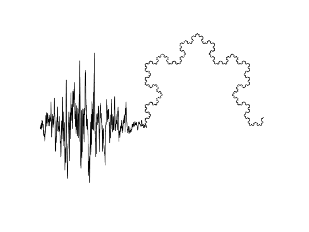

## *The wavelet - RnB (Fig. M1, M2) *

#### *(J.M. Lina, M-C. Foti, 2024)*

#### The main reference: J. Dubé et al., *Rhythms and Background (RnB): the spectroscopy of sleep recordings*, 2024 

- **a) load of 520 epochs (iEEG recorded in the hippocampus):  **

- Exemple of one epoch.

- **b)** **Fractional Spline Wavelet**

- one exemple of a wavelet used in RnB (co-registred with a cosine function with the same 'main' frequency)

- **c) The Discrete Wavelet Transform** of the signal shown in (a)

- each 'box' is a wavelet coefficient, at a specific scale and with an associated 'time scale' 

- The darker, the larger is the wavelet coefficient

- **d) Wavelet log-power**

- this figure displays the linear regression of the log-power of the discrete wavelet coefficient with respect to the scales

- **e) The Discrete Wavelet Transform of the Rhythmic RnB signal**

- this figure shows the wavelet coeffcients of the rhythms present in the exemple shown in (a)

- **f) The Wavelet power of the rhythmic signals**

- this figure gives also the approximate correspondance between scales and frequency bands (x axis)

We recommand to execute sequentially the following sections:

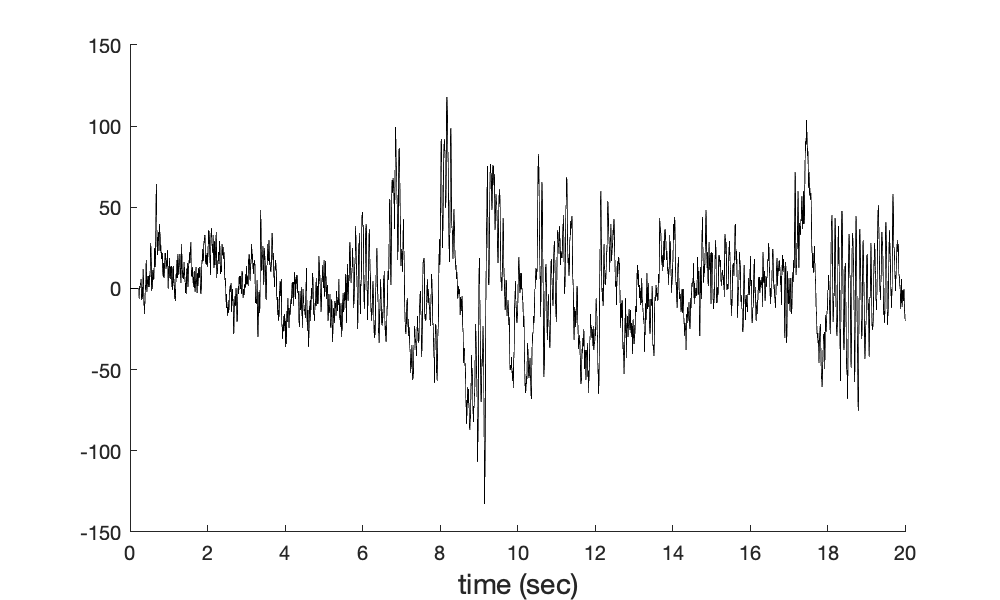

  -- This signal is one epoch (30 seconds) of a series
     of 520 epochs recorded in the hippocampus (human).

 
clc; clear; close all;
addpath(genpath('./ressources'));
% Chargement d'un signal
load ('./data/FigM1_data.mat','time','signal','fs')
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This example contains 520 epocs of signals (signal)            %
% The frequency sampling is fs.                                  %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Size:
[Ne,Nt] = size(signal);
% An example of time series: 
s500 = signal(500,:);
f1 = make_fig1(time,s500);

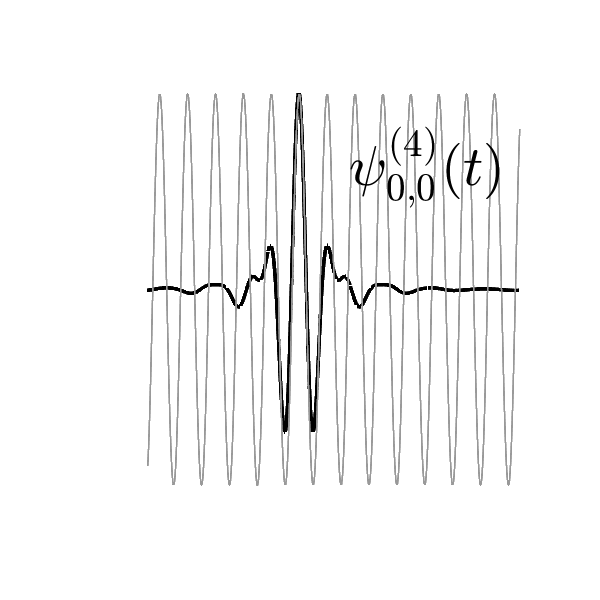

  -- This is a wavelet at scale 2^0 = 1 and centered at
     time = 0. The regularity parameter is alpha = 4 and
     the assymetry parameter is tau = 0. This wavelet is
     built from the 'FracSpline' package developped by 
     T. Blu and M. Unser.
     The plot also display the sine function corresponding to
     the oscillation of the wavelet (here 5/6 Hz)



 
addpath(genpath('./ressources'));
% Maximum scales and labels:
J = nextpow2(Nt);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Choose a fractional spline wavelet transform : psi(t)  %
alpha = 4;            % Real value larger than -0.5      %
tau = 0;              % Real value between -0.5 and +0.5 %
type = 'ortho';                                          %
[t,psi] = fractsplinewaveletfunction(alpha,tau,type,J-2);%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f2 = make_fig2(t,psi);

 -- We show 968 wavelet coeff among 4096
    they account for 99.00 % of the total power.


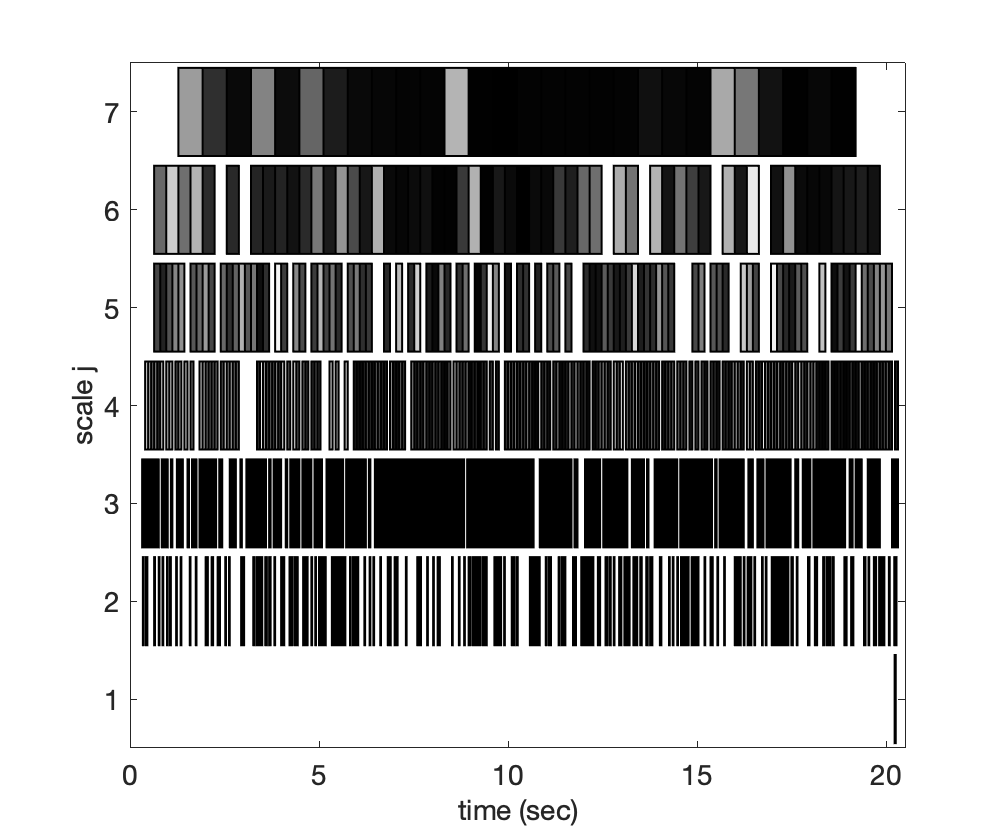

 
addpath(genpath('./ressources'))
% Definition of synthesis scaling function and the spline wavelet (filters) %
alpha = 4;            % Real value larger than -0.5                         %
tau = 0;              % Real value between -0.5 and +0.5                    %
type = 'ortho';                                                             %
J = 7;                % Number of decomposition levels                      %
[analysisfilter,~] = FFTfractsplinefilters(Nt,alpha,tau,type);              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Perform a fractional spline wavelet transform of the signal: %%% 
wavelet.scales_j = 1:J;                                          %
wavelet.time = time;                                             %
w = FFTwaveletanalysis1D(s500,analysisfilter,J);                 %
ws500 = formater_fracSpline_result(w,wavelet);                   %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Display (99% of the global power) 
wavelet.pc_power = 99;
f3 = make_fig3(ws500,wavelet);

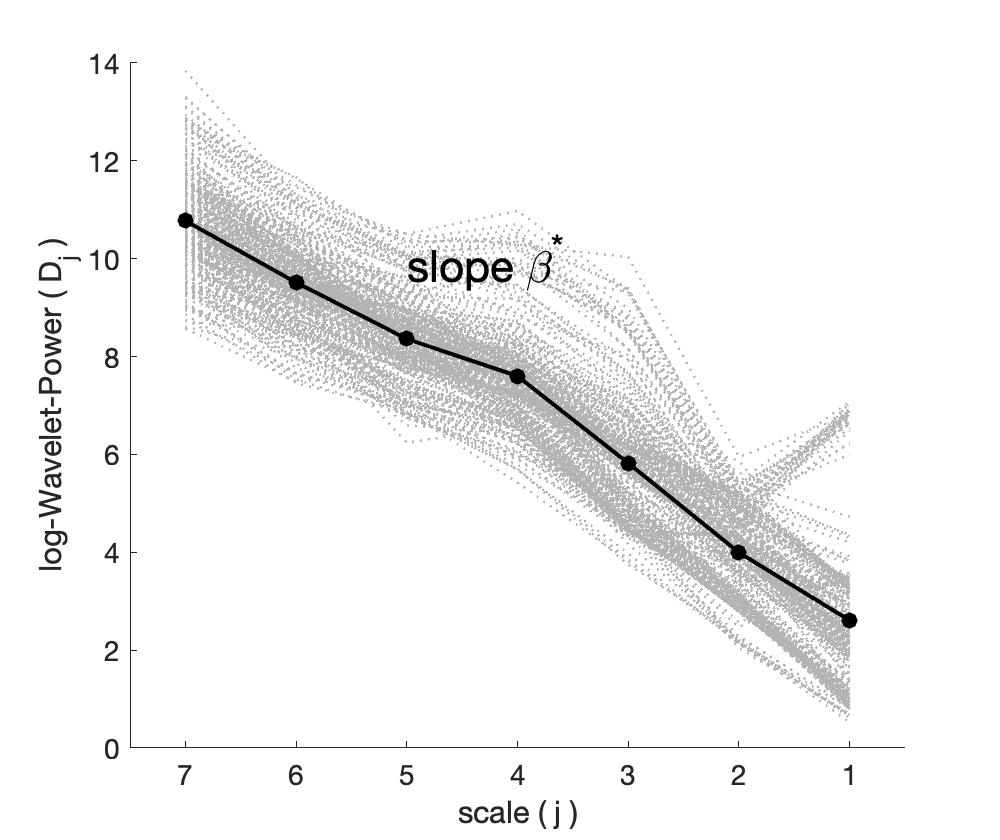

 

addpath(genpath('./ressources'))
% Definition of synthesis scaling function and the spline wavelet (filters) %
alpha = 4;            % Real value larger than -0.5                         %
tau = 0;              % Real value between -0.5 and +0.5                    %
type = 'ortho';                                                             %
J = 7;                % Number of decomposition levels                      %
[analysisfilter,~] = FFTfractsplinefilters(Nt,alpha,tau,type);              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
wavelet.scales_j = 1:J;                                           %
wavelet.time = time;                                              %
WavPow = zeros(300,J);                                            %
for epo = 1:300                                                   %
    w = FFTwaveletanalysis1D(signal(epo,:),analysisfilter,J);     %
    wData = formater_fracSpline_result(w,wavelet);                %
    [~,logPw] = Wavelet_Power(wData,J);                           %
    WavPow(epo,:) = logPw;                                        %
end                                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f4 = make_fig4(WavPow,J,fs);

 -- We show 652 wavelet coeff among 4096
    they account for 99.00 % of the total power.


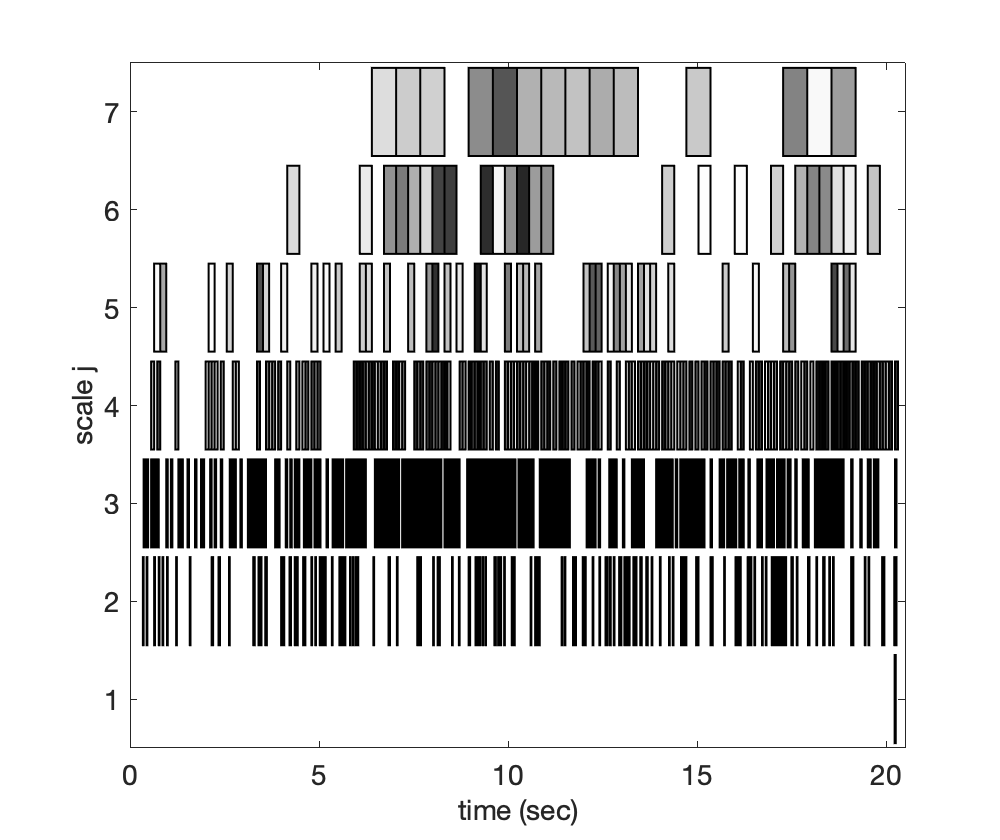

 
load ('./data/FigM1_data.mat','Rsignal')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Spline wavelet analysis of the Rhythmic signal of s500       %
Rs500 = Rsignal(500,:);                                        %
wavelet.scales_j = 1:J;                                        %
wavelet.time = time;                                           %
w = FFTwaveletanalysis1D(Rs500,analysisfilter,J);              %
wDataR500 = formater_fracSpline_result(w,wavelet);             %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Display of 99% wavelet power of Rs500 
wavelet.pc_power = 99;
f3b = make_fig3(wDataR500,wavelet);

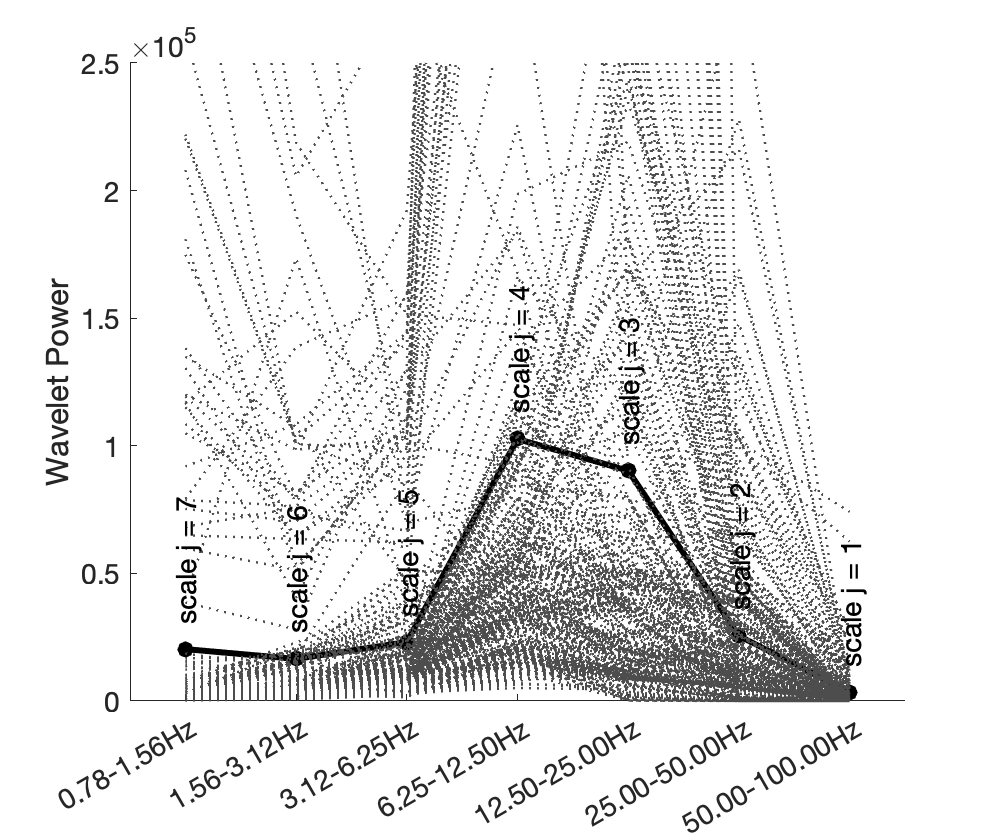

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fractional Spline wavelet transform of the 300 first Rhythmic %
% signals                                                       %
% WavePowR will accumulate the power across the J scales:       %
WavPowR = zeros(300,J);                                         %
for epo = 1:300                                                 %
    w = FFTwaveletanalysis1D(Rsignal(epo,:),analysisfilter,J);  %
    wData = formater_fracSpline_result(w,wavelet);              %
    [PwR,~] = Wavelet_Power(wData,J);                           %
    WavPowR(epo,:) = PwR;                                       %
end                                                             %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f5 = make_fig5(WavPowR,J,fs);

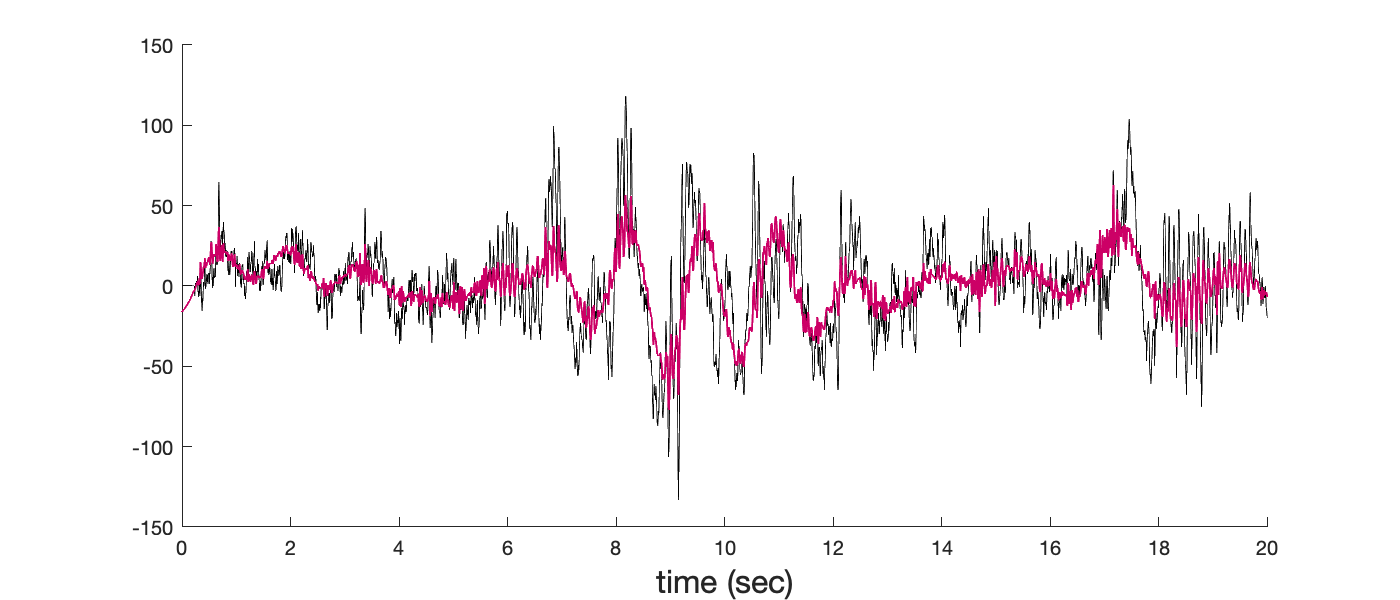

 
% scaling = FFTwaveletsynthesis1D(w500,synthesisfilter,J); %%%%%
[~,synthesisfilter] = FFTfractsplinefilters(Nt,alpha,tau,type);%
scaling = comp_scal(s500,analysisfilter,synthesisfilter,J);    %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
OPTIONS.schrinkage = 1;                                        %
OPTIONS.fractional = 1;                                        %
OPTIONS.J      = J;                                            %
OPTIONS.jnoise = 1;                                            %
OPTIONS.alpha0 = 4;                                            %
OPTIONS.beta   = [];                                           %
[sR,wR] = wRnB_extract_Rhythmic_signals(s500,OPTIONS);         %
Rs500 = scaling+sR;                                            %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f6 = make_fig6(time,s500,Rs500);

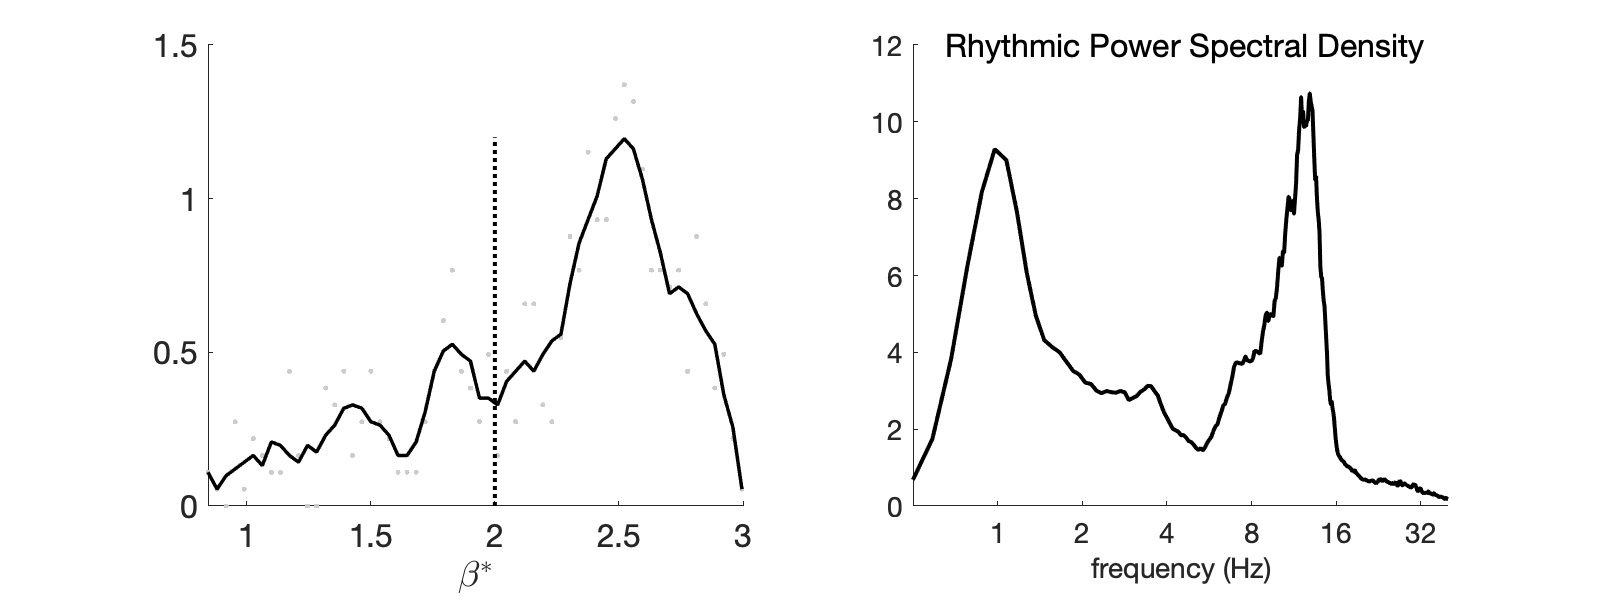

 
load('./data/FigM2_data.mat')
f7 = make_fig7(B300,fr300,P300);